load('Figure_codes/Figure_data/Brain-Behavior.mat');


signature_response_top = groupsummary(Brain_Behavior_data, ...
    ["Rnum","timesObjectPresented_block"], ...
    "mean", ...
    "signature_z_block");
reshaped_signature_response_top = transpose(reshape(signature_response_top.mean_signature_z_block,3,43));
signature_response_object = groupsummary(Brain_Behavior_data, ...
    ["Rnum","object_rank"], ...
    "mean", ...
    "signature_z_block");
reshaped_signature_response_object = transpose(reshape(signature_response_object.mean_signature_z_block,6,43));



font_size = 12;
line_width = 1;
marker_size = 5;
tick_lengh = 0.02;
colors_group = flip([140, 140, 193;143, 158, 202;169, 195, 222;201, 218, 234]/255);


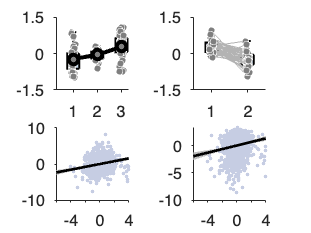

figure()
subplot(2,2,1)
bx = daboxplot(reshaped_signature_response_top,'colors','w','whiskers',1,'scatter',1,'scattercolors',{'k','w'},'scattersize', marker_size*5,'scatteralpha',0.5,'outliers',0,'lineWidth',1.5,'boxwidth',1.5,'boxspacing',2,'boxspacing',2);
bx.bx(1).FaceColor = colors_group(1,:);
bx.bx(2).FaceColor = colors_group(2,:);
bx.bx(3).FaceColor = colors_group(3,:);
hold on;
lineplot_columns(1:3,reshaped_signature_response_top, 'color', [0 0 0], 'markerfacecolor', [.5 .5 0.5]);
ylim([-1.5 1.5]);
yticks([-1.5, 0, 1.5]);
xlim([0.3,3.3]);
xlabel([]);
box off; grid off; 
set(gca, 'FontSize', font_size, 'LineWidth', line_width,'TickLength', [0.03, 0.03], 'TickDir', 'out');
axis square
subplot(2,2,2)
bx = daboxplot(reshaped_signature_response_object(:,[1,6]),'colors','w','whiskers',1,'scatter',1,'scattercolors',{'k','w'},'scattersize', marker_size*5,'scatteralpha',0.5,'withinlines',1,'outliers',0,'lineWidth',1.5,'boxspacing',5);
bx.bx(1).FaceColor = colors_group(4,:);
bx.bx(2).FaceColor = colors_group(1,:);
ylim([-1.5 1.5]);
yticks([-1.5, 0, 1.5]);
xlim([0.5,2.5]);
xlabel([]);
box off; grid off; 
set(gca, 'FontSize', font_size, 'LineWidth', line_width,'TickLength', [0.03, 0.03], 'TickDir', 'out');
axis square

subplot(2,2,3)
scatter(Brain_Behavior_data.signature_z_block, Brain_Behavior_data.SMA_z, ...
        marker_size*1.5, colors_group(3,:), 'filled', ...
        'MarkerFaceAlpha', 0.5);
hold on;
T = LMM_fixed_SMA_signature;
x = T.x; fit = T.fit;
lower = T.lower; upper = T.upper;
color = [218 227 243]/255;

fill([x; flipud(x)], [upper; flipud(lower)], ...
     [0.5 0.5 0.5],'EdgeColor','none','FaceAlpha',0.5);
plot(x,fit,'k-','LineWidth',line_width*2);

set(gca,'FontSize',font_size,'LineWidth',line_width, ...
    'TickDir','out','TickLength',[tick_lengh tick_lengh]);
%xlim([0.95 3.05]); ylim([-1 1]);
%xticks([1 2 3]); yticks([-1 0 1]);

pbaspect([1 1 1]);
box off;
subplot(2,2,4)
scatter(Brain_Behavior_data.signature_z_block, Brain_Behavior_data.NE_z, ...
        marker_size*1.5, colors_group(3,:), 'filled', ...
        'MarkerFaceAlpha', 0.5);
hold on 
T = LMM_fixed_NE_signature;
x = T.x; fit = T.fit;
lower = T.lower; upper = T.upper;
color = [218 227 243]/255;

fill([x; flipud(x)], [upper; flipud(lower)], ...
     [0.5 0.5 0.5],'EdgeColor','none','FaceAlpha',0.5);
plot(x,fit,'k-','LineWidth',line_width*2);

set(gca,'FontSize',font_size,'LineWidth',line_width, ...
    'TickDir','out','TickLength',[tick_lengh tick_lengh]);
%xlim([0.95 3.05]); ylim([-1 1]);
%xticks([1 2 3]); yticks([-1 0 1]);

pbaspect([1 1 1]);
box off;